# Crystal lattice image and distortion of that image v.3

This is a more efficient, neater, and better-documented version on LaD2.

## 1    The crystal lattice

For reference, shown here is an undistorted crystal lattice (basically a product of sinusoids) produced by substituting $\vec{u}=\vec{0}$ to equation S5 of Lawler-Fujita (2010)'s supplementary material.

Declaring basic values.

image_length = 1024;
image_height = 1024;
atom_diameter = 16;

Q_x = [1 0];
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);

Creating the lattice.

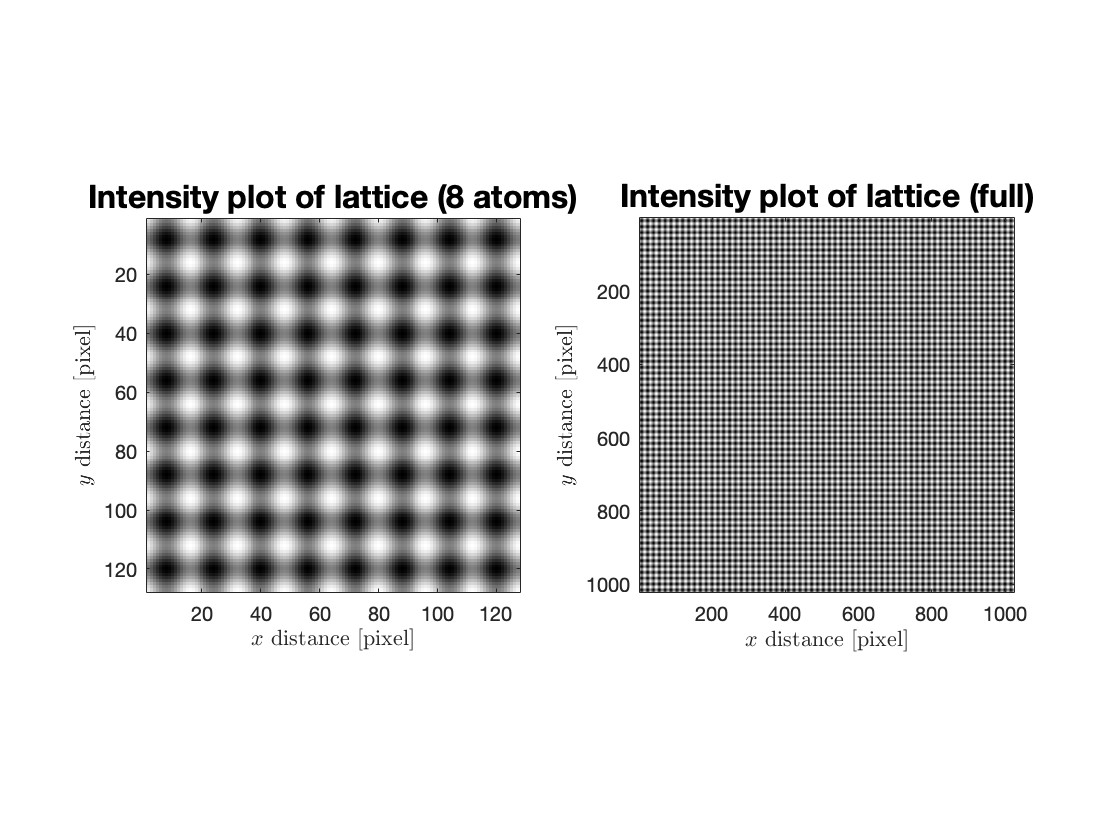

[x,y] = meshgrid(1:image_length,1:image_height);
lattice = normies(cos(Q_x(1)*x+Q_x(2)*y)+cos(Q_y(1)*x+Q_y(2)*y));
comboPlot(lattice,"lattice",atom_diameter);

colormap(gray);

Applying the Fourier transform to the created image.

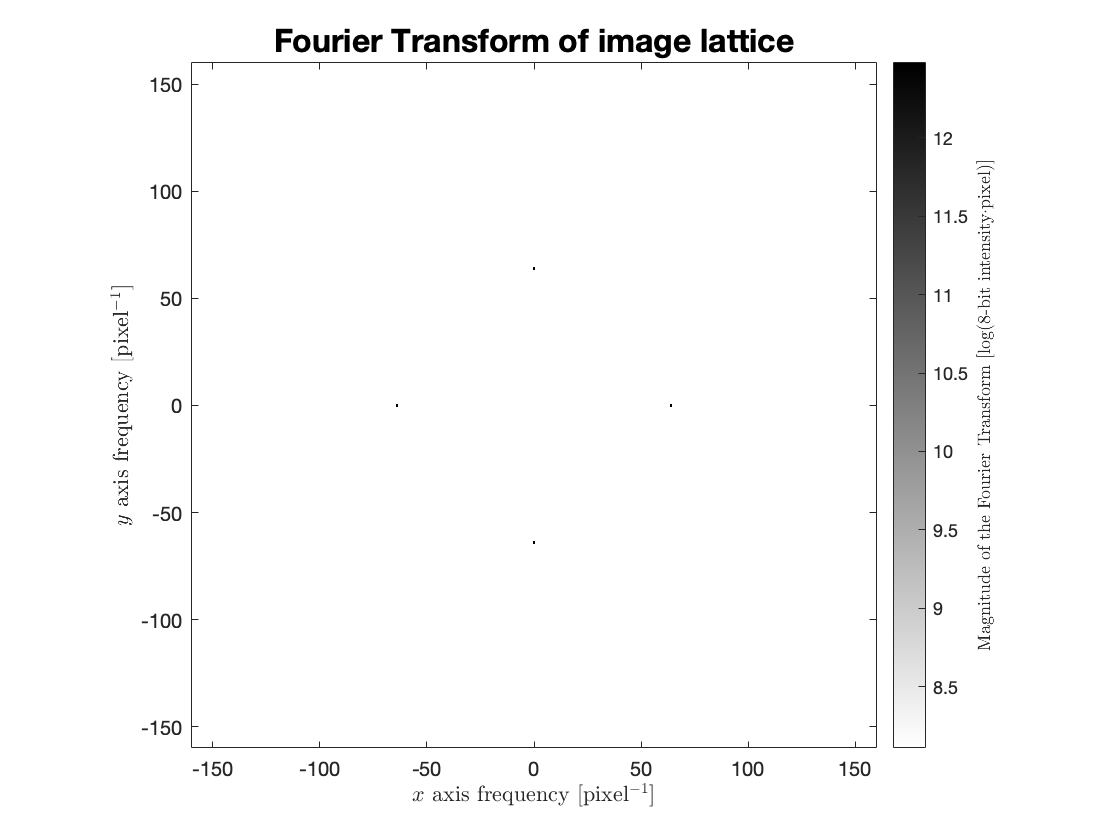

lattice_fft = myFFT(lattice,"lattice");

## 2    A distorted crystal lattice

We create a distorted lattice with the displacement vector $\vec{u}=y\cdot\hat{x}+0\cdot\hat{y}$.

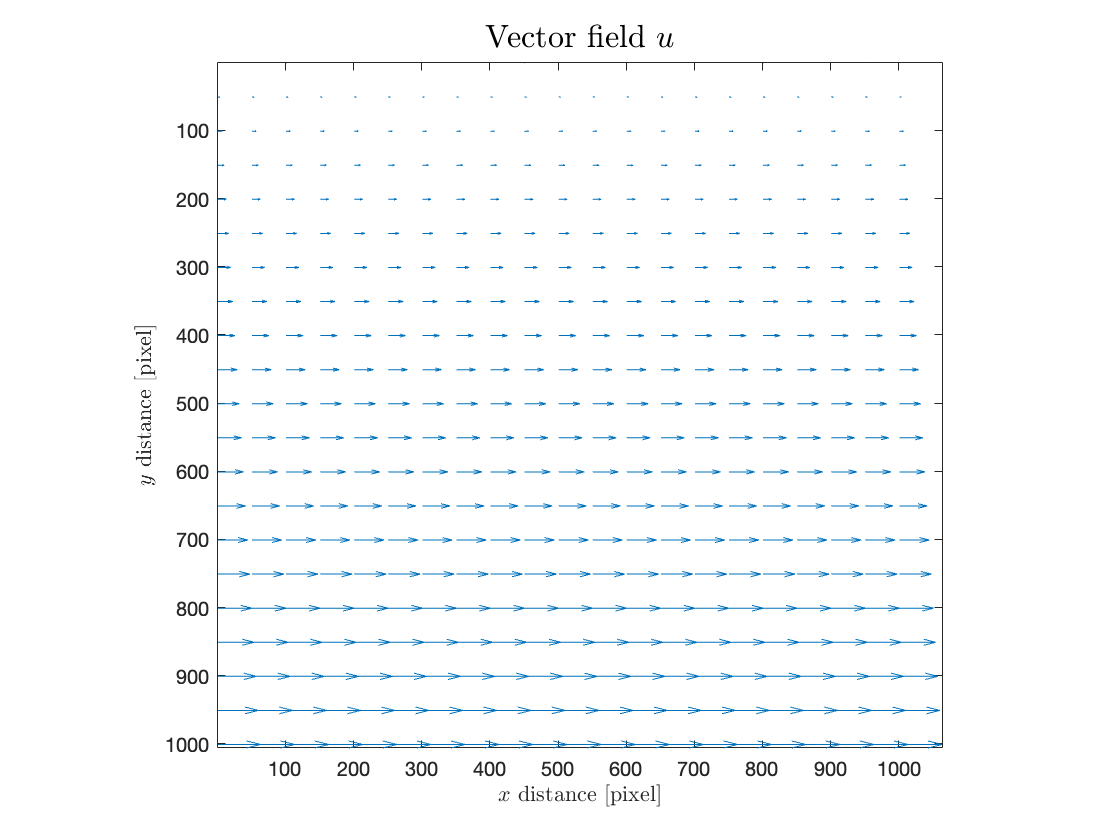

u = uCreate(image_height,image_length,image_height/atom_diameter);

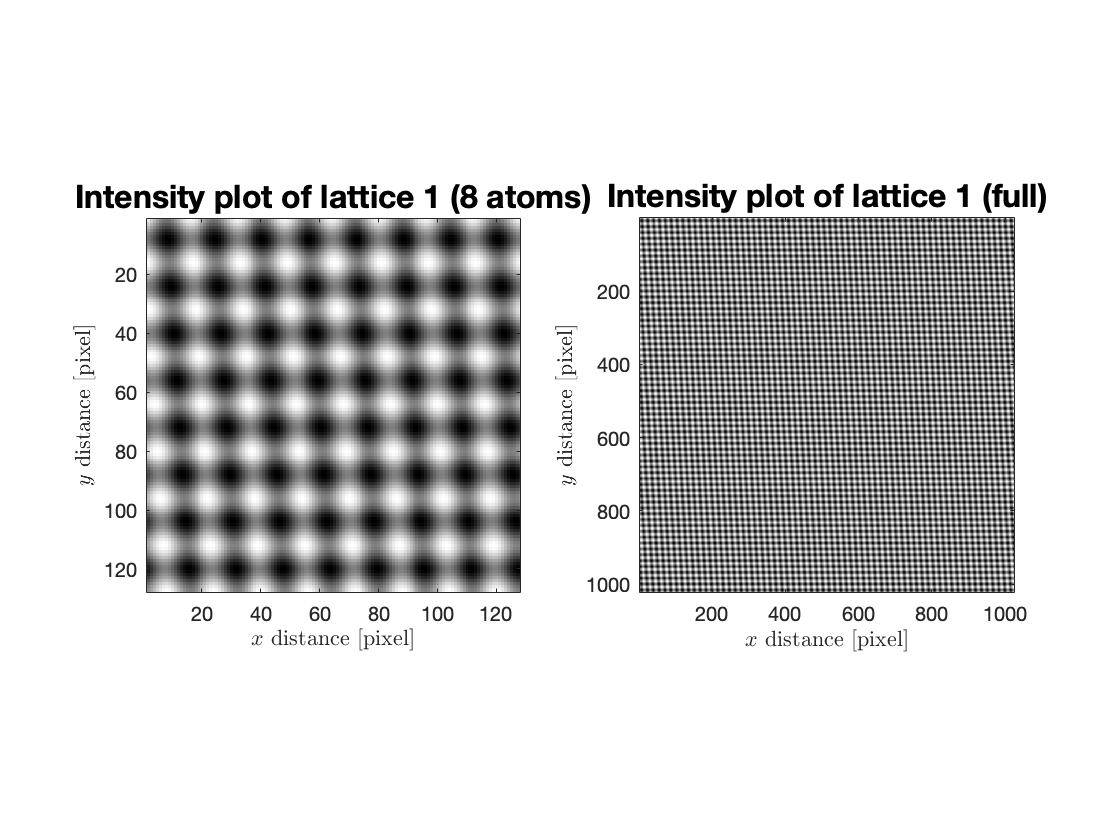

% the last parameter just scales the magnitudes of the vectors in u

lattice1 = normies(uTransform(u,Q_x,Q_y));
comboPlot(lattice1,"lattice 1",atom_diameter);

Applying the Fourier transform to the distorted image.

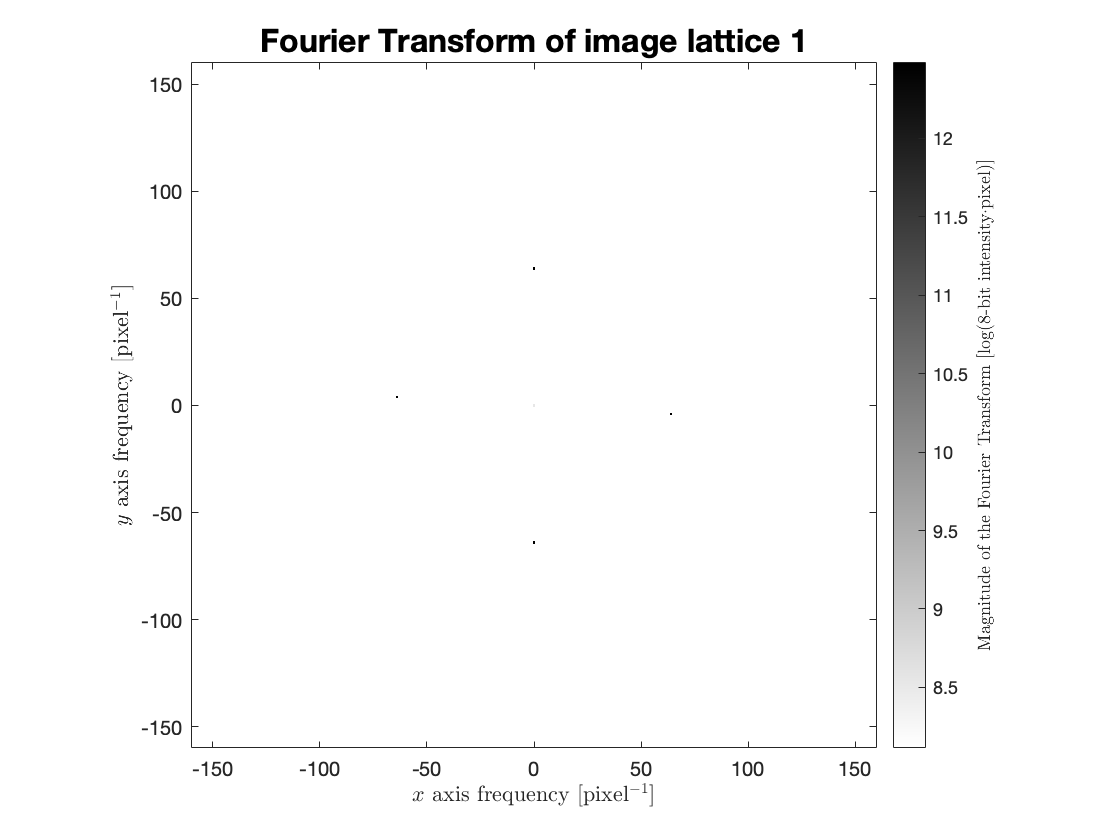

lattice1_fft = myFFT(lattice1,"lattice 1");

## 3    Calculating the vector field $u$

We're going to pretend that we don't know the displacement vector field that resulted to lattice1. Let's calculate $u$ only from the matrix/image lattice1.

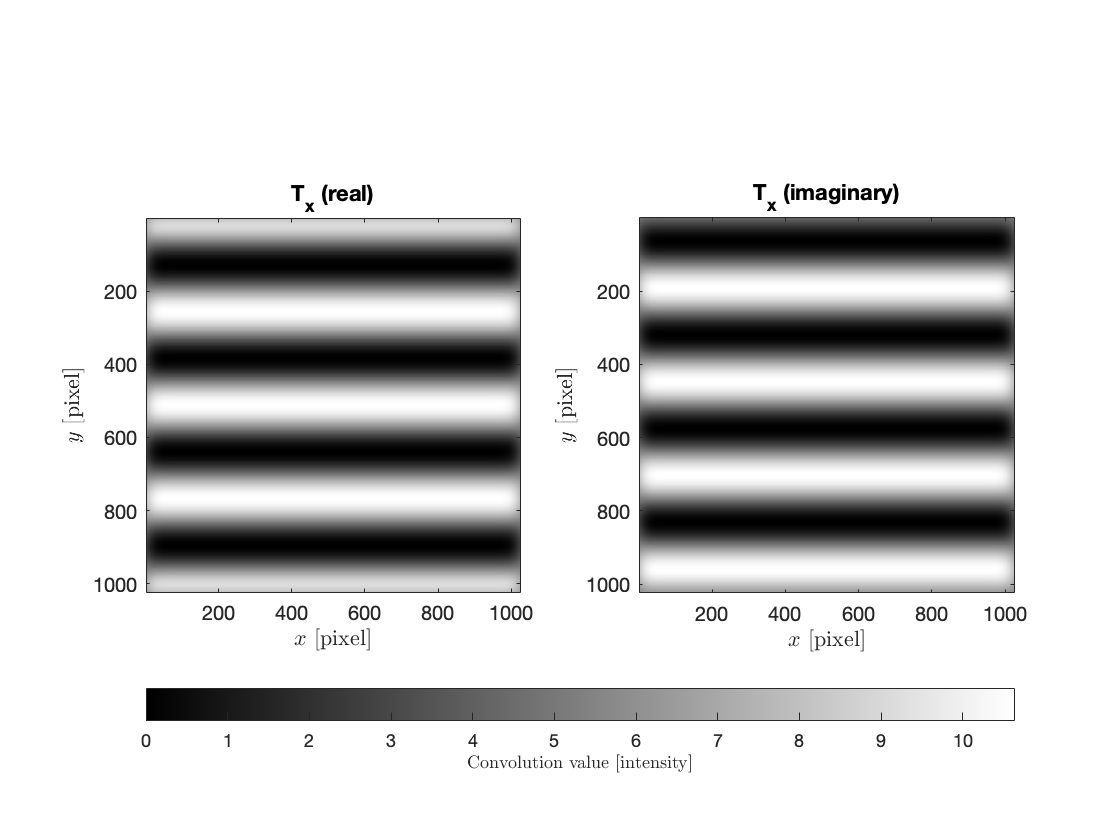

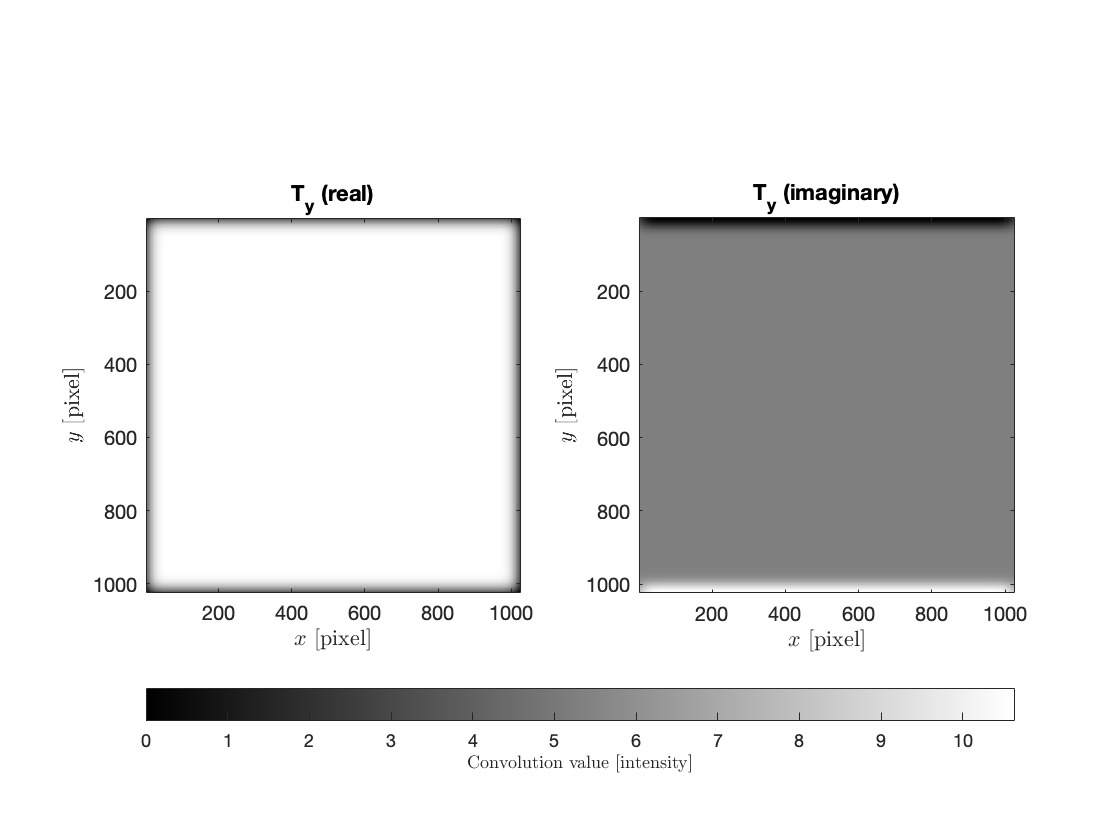

lambda = 0.05;

tic
ucalc = myConv(lattice1,Q_x,Q_y,lambda);

toc

Elapsed time is 19.023427 seconds.


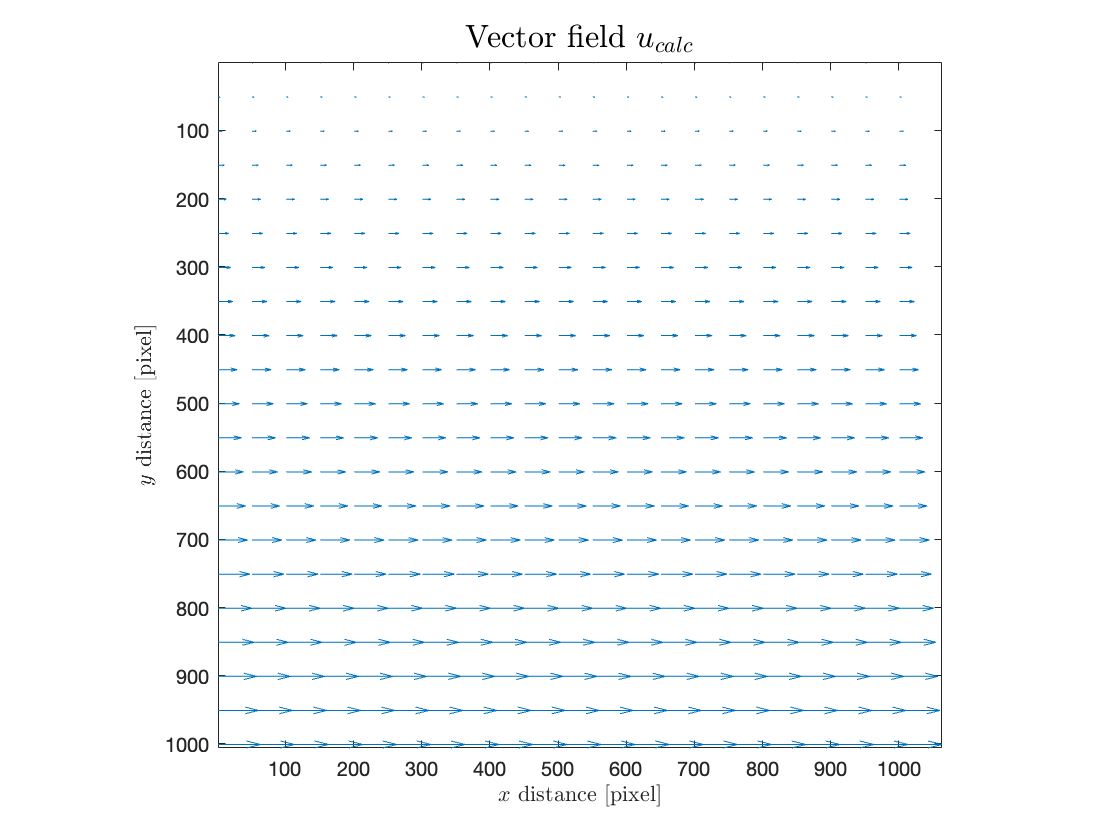

uPlot(ucalc,"$u_{calc}$");

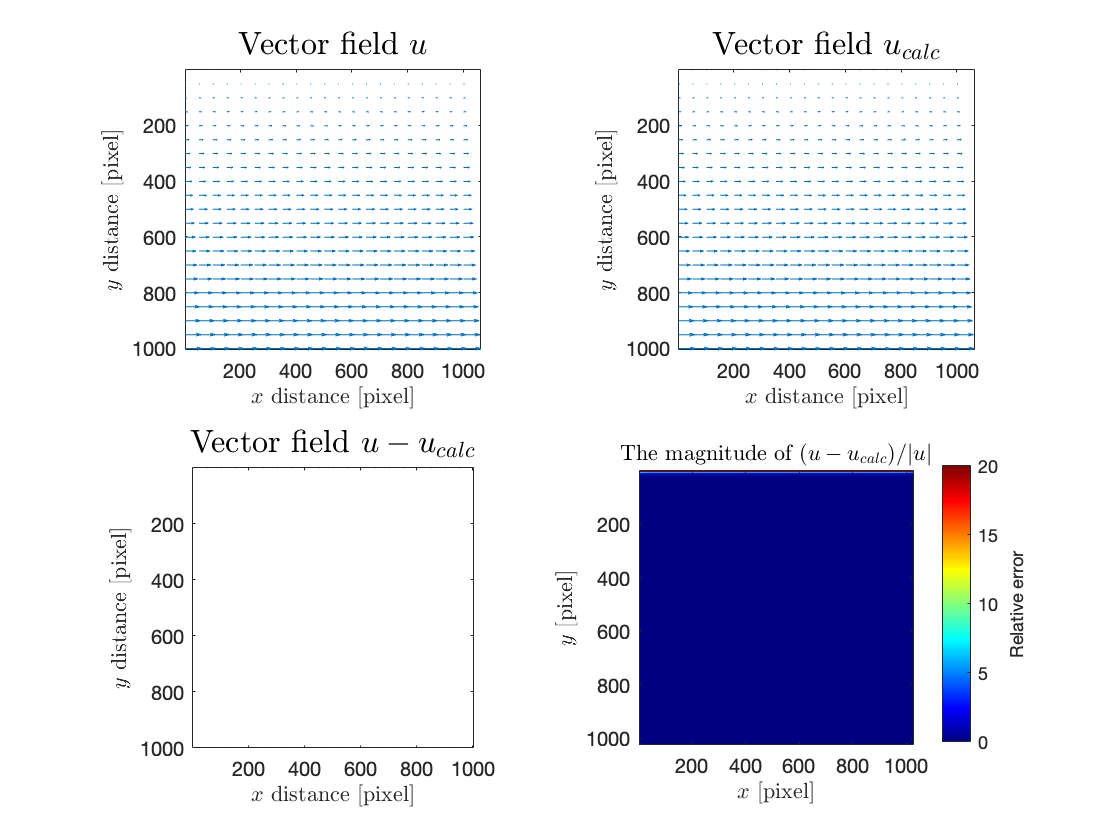


% just to plot the difference in the defined and calculated u
subplot(2,2,1);
uPlot(u,"$u$");
subplot(2,2,2);
uPlot(ucalc,"$u_{calc}$");
subplot(2,2,3);
uPlot(ucalc-u,"$u-u_{calc}$");
subplot(2,2,4);
colormap(jet);
imagesc(sqrt(((ucalc(:,:,1)-u(:,:,1)).^2+(ucalc(:,:,2)-u(:,:,2)).^2)./(u(:,:,1).^2+u(:,:,2)).^2),[0 20]);
title("The magnitude of $(u-u_{calc})/|u|$","Interpreter","latex");
xlabel("$x$ [pixel]","Interpreter","latex");
ylabel("$y$ [pixel]","Interpreter","latex");
axis image
c = colorbar;
c.Label.String = "Relative error";

figure;

Notice the wanky edges on the $T_x$ and $T_y$ plots. That's because the convolution function in MatLab padds the matrices with zeros on the edges.

## Functions

function latticePlot(P0,nm1,r,num)
    % P0 is the image (uint8); nm1 is the title; r, num specify the view
    
    imagesc(P0);
    colormap(gray);
    axis image
    if nargin<4
        num = 8;
        if nargin>2
            xlim([1 r*num]);
            ylim([1 r*num]);
        end
    else
        xlim([1 r*num]);
        ylim([1 r*num]);
    end
    
    xlabel("$x$ distance [pixel]","Interpreter","latex");
    ylabel("$y$ distance [pixel]","Interpreter","latex");
    t = title("Intensity plot of " + nm1);
    t.FontSize = 16;
end

function A = normies(A, lim)
    % I'm creating this function cuz MATLAB's normalize() is dumb
    if nargin<2
        lim = [-1 1];
    end
    A = lim(1)+(A-min(A,[],"all"))./(max(A,[],"all")-min(A,[],"all")).*(lim(2)-lim(1));
end

function comboPlot(P0, nm, a)
    figure;
    subplot(1,2,1);
    latticePlot(P0,nm + " (8 atoms)",a,8);
    subplot(1,2,2);
    latticePlot(P0,nm + " (full)");
    figure;
end

function [Q, idx, idy] = myFFT(P, nm, dip)
    % P is the image; r, n, noisy specify the colorbar range
    % Q is the fft; idx, idy are the indices of Qx, Qy
    
    sp = size(P);
    Q = fft2(P);
    Q1 = log(abs(Q));
    Q2 = Q1;
    Q2(isinf(Q2)) = nan;
    [~,idx] = max(Q2(2:end,1),[],"omitnan");
    [~,idy] = max(Q2(1,2:end),[],"omitnan");
%     idx = idx + 1;  % to make up for the omitted first index
%     idy = idy + 1;
    
    Q1 = fftshift(Q1);
    
    if nargin<3
        dip = [0.65 1];
    end
    
    sec_max = min(maxk(max(Q1),2)); % for scaling the colorbar
    imagesc(-sp(1)/2,-sp(2)/2,Q1, sec_max*dip);
    colormap(flipud(gray));
    set(gca,"YDir","normal");
    axis equal tight
    c = colorbar;
    
    xyl = max(idx,idy);
    xlim([-xyl*2.5 xyl*2.5]); % comment these to view whole Fourier transform
    ylim([-xyl*2.5 xyl*2.5]);
    xlabel("$x$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
    ylabel("$y$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
    c.Label.String = "Magnitude of the Fourier Transform [log(8-bit intensity$\cdot$pixel)]";
    c.Label.Interpreter = "Latex";
    t = title("Fourier Transform of image " + nm);
    t.FontSize = 16;
end

function s = uCreate(h,l, scale_mag)
    % just to avoid clutter
    s = zeros(h,l,2);
    scale_coor = 1; % to scale the coordinates of the vector field
    if nargin<3
        scale_mag = 15; % to scale the magnitude of the vectors in the vector field
    end
    [x,y] = meshgrid(1:l,1:h);
    x = scale_coor.*x./l;
    y = scale_coor.*y./h;
    
    % change these to change the vector field u
    s(:,:,1) = y*scale_mag;
    s(:,:,2) = 0*scale_mag;
    
    uPlot(s,"$u$");
end

function uPlot(s,nm)
    % s is the 3D array that contains information about the vector field
    
    [h,l,~] = size(s);
    [v,w] = meshgrid(1:l,1:h);
    
    skipx = ceil(50*l/1024);
    skipy = ceil(50*h/1024);
    
    quiver(v(1:skipx:end,1:skipy:end),w(1:skipx:end,1:skipy:end), ...
        s(1:skipx:end,1:skipy:end,1),s(1:skipx:end,1:skipy:end,2),0); % remove 0 to auto-scale
    t = title("Vector field " + nm,"Interpreter","latex");
    xlabel("$x$ distance [pixel]","Interpreter","latex");
    ylabel("$y$ distance [pixel]","Interpreter","latex");
    set(gca,"YDir","reverse");
    axis equal tight;
    t.FontSize = 16;
end

function P = uTransform(s,qx,qy)
    [h,l,~] = size(s);
    [x,y] = meshgrid(1:l,1:h);
    P = cos(qx(1)*(x-squeeze(s(:,:,1)))+qx(2)*(y-squeeze(s(:,:,2))))...
        +cos(qy(1)*(x-squeeze(s(:,:,1)))+qy(2)*(y-squeeze(s(:,:,2))));
    % note the complicated expression
    % That's because I'm assuming that the quantities qx and qy are vectors
end

function blat = myConv(lat,qx,qy,lamb)
    blat = zeros(size(lat));
    sp = size(lat);
    [x,y] = meshgrid(1:sp(2),1:sp(1));
    
    % define the Gaussian
    G = fspecial('gaussian',[sp(1) sp(2)],1/lamb).*lamb/sqrt(2*pi);
    
    % define the other factors to be convoluted
    Fx = lat.*exp(-1i*(qx(1)*x+qx(2)*y));
    Fy = lat.*exp(-1i*(qy(1)*x+qy(2)*y));
    
    % convolve the functions
    lat_x = conv2(Fx,G,'same');
    lat_y = conv2(Fy,G,'same');
    
    % plot the results
    plotConv(lat_x,"T_x");
    plotConv(lat_y,"T_y");
    
    % same with all the functions, note the vector representations of qx and qy
    pa = -unwrap(angle(lat_x*2));
    pb = -unwrap(angle(lat_y*2));
    blat(:,:,1) = (pa*qy(2)-pb*qx(2))./(qx(1)*qy(2)-qy(1)*qx(2));
    blat(:,:,2) = (pa*qy(1)-pb*qx(1))./(qx(2)*qy(1)-qy(2)*qx(1));
end

function plotConv(lat,nm)
    figure;
    colormap(gray);
    subplot(1,2,1);
    imagesc(real(lat));
    title(nm + " (real)");
    xlabel("$x$ [pixel]","Interpreter","latex");
    ylabel("$y$ [pixel]","Interpreter","latex");
    axis image
    subplot(1,2,2);
    imagesc(imag(lat));
    title(nm + " (imaginary)");
    xlabel("$x$ [pixel]","Interpreter","latex");
    ylabel("$y$ [pixel]","Interpreter","latex");
    axis image
    
    % for the common colorbar
    h = axes('visible', 'off');
    caxis(h, [0, 10.6267]);
    c = colorbar(h, 'Location','southoutside');
    c.Label.String = "Convolution value [intensity]";
    c.Label.Interpreter = "Latex";
    figure;
end